clc
clear all
load('dataset1.mat')
load('dataset2.mat')

## K-means

X = dataset1;
k = 10;
no_iter = 50;
initializer = 1;

[c_idx,C,cost] = mykmeans(X,k,no_iter,initializer);

Initializer: random


cost

cost = 1.4025e+03

gscatter(X(:,1),X(:,2),c_idx)
hold on 
scatter(C(:,1),C(:,2),"LineWidth",2,"DisplayName",'Center')
hold off
xlabel('feature 1',"FontSize",16)
ylabel('feature 2',"FontSize",16)


all_cost = [];
for k = 2: 50
    COSTs = zeros(5,1);
    for i = 1:5
        [c_idx,C,cost] = mykmeans(X,k,no_iter,initializer);
        C_IDXs{i} = {c_idx};
        Cs{i} = {C};
        COSTs(i) = cost;
    end
    [M,IDX] = min(COSTs);
    all_cost = [all_cost;M];
end
plot(2: 50,all_cost,"LineWidth",2)
xlabel('k',"FontSize",16)
ylabel('cost',"FontSize",16)


## K-means ++

initializer = 2;
k = 8
[c_idx,C,cost] = mykmeans(X,k,no_iter,initializer);
cost
gscatter(X(:,1),X(:,2),c_idx)
hold on 
scatter(C(:,1),C(:,2),"LineWidth",2,"DisplayName",'Center')
hold off
xlabel('feature 1',"FontSize",16)
ylabel('feature 2',"FontSize",16)


all_cost = [];
for k = 2: 50
    COSTs = zeros(5,1);
    for i = 1:5
        [c_idx,C,cost] = mykmeans(X,k,no_iter,initializer);
        C_IDXs{i} = {c_idx};
        Cs{i} = {C};
        COSTs(i) = cost;
    end
    [M,IDX] = min(COSTs);
    all_cost = [all_cost;M];
end
plot(2: 50,all_cost)
xlabel('k',"FontSize",16)
ylabel('cost',"FontSize",16)


# On test data set 2

X = dataset2;
k = 10;
no_iter = 50;
initializer = 1;

[c_idx,C,cost] = mykmeans(X,k,no_iter,initializer);
cost
for i = 1:k
    data = X(c_idx==i,:);
    scatter3(data(:,1),data(:,2),data(:,3),"DisplayName",string(i));
    hold on 
end

hold on 
scatter(C(:,1),C(:,2),'k',"LineWidth",4,"DisplayName",'Center')
hold off
legend
xlabel('feature 1',"FontSize",16)
ylabel('feature 2',"FontSize",16)
zlabel('feature 3',"FontSize",16)

all_cost = [];
for k = 2: 50
    COSTs = zeros(5,1);
    for i = 1:5
        [c_idx,C,cost] = mykmeans(X,k,no_iter,initializer);
        C_IDXs{i} = {c_idx};
        Cs{i} = {C};
        COSTs(i) = cost;
    end
    [M,IDX] = min(COSTs);
    all_cost = [all_cost;M];
end
plot(2: 50,all_cost,"LineWidth",2)
xlabel('k',"FontSize",16)
ylabel('cost',"FontSize",16)

### K-means ++

% ++ init
initializer = 2;k = 10;
[c_idx,C,cost] = mykmeans(X,k,no_iter,initializer);
k = 10
cost
for i = 1:k
    data = X(c_idx==i,:);
    scatter3(data(:,1),data(:,2),data(:,3),"DisplayName",string(i));
    hold on 
end
scatter(C(:,1),C(:,2),'k',"LineWidth",4,"DisplayName",'Center')
legend
xlabel('feature 1',"FontSize",16)
ylabel('feature 2',"FontSize",16)
zlabel('feature 3',"FontSize",16)
hold off


all_cost = [];
for k = 2: 50
    COSTs = zeros(5,1);
    for i = 1:5
        [c_idx,C,cost] = mykmeans(X,k,no_iter,initializer);
        C_IDXs{i} = {c_idx};
        Cs{i} = {C};
        COSTs(i) = cost;
    end
    [M,IDX] = min(COSTs);
    all_cost = [all_cost;M];
end
plot(2: 50,all_cost,"LineWidth",2)
xlabel('k',"FontSize",16)
ylabel('cost',"FontSize",16)

# Agglomerative hierarchical cluster tree

## Data set 1

X = dataset1;
Z = linkage(X,'average')

Z = 	1.0e+03 *

    1.6220    1.7110    0.0000
    0.7360    0.8030    0.0000
    2.0220    2.8760    0.0000
    0.7240    0.7980    0.0000
    2.5970    2.9230    0.0000
    2.3170    2.9930    0.0000
    1.5710    2.8940    0.0000
    0.6820    0.6900    0.0000
    0.5870    0.9100    0.0000
    1.1210    2.9330    0.0000


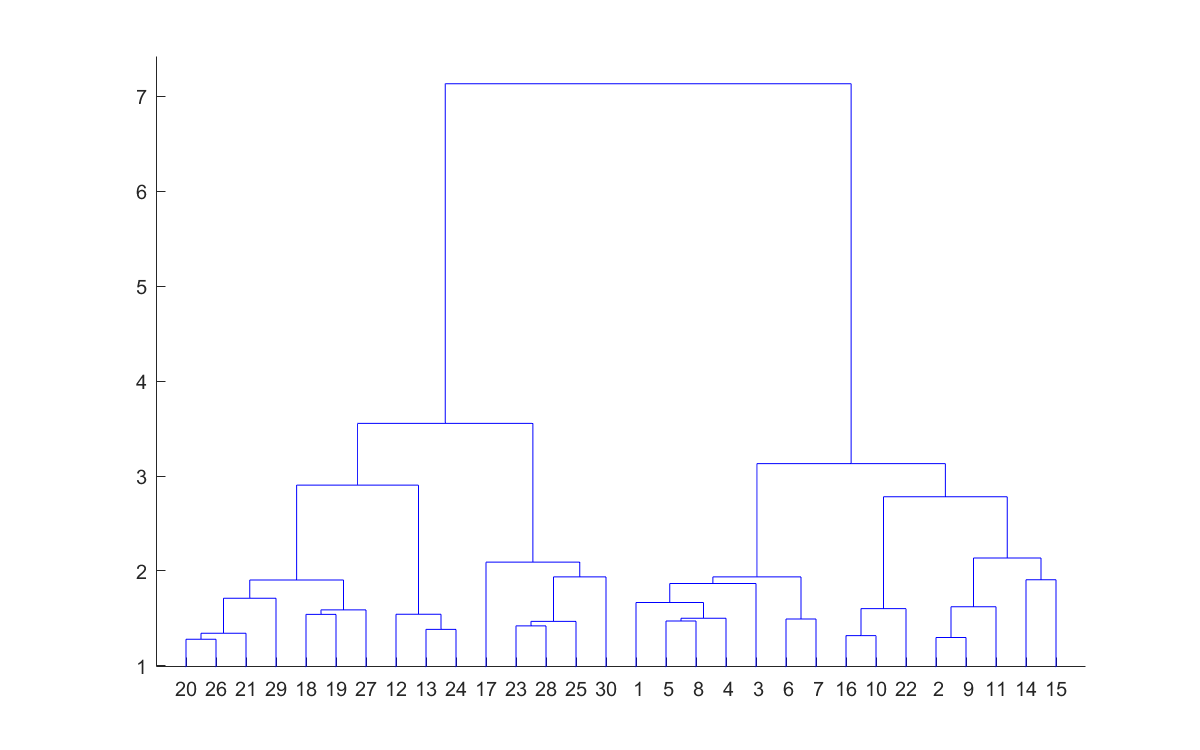

dendrogram(Z)

Y = inconsistent(Z)

Y =     0.0006         0    1.0000         0
    0.0007         0    1.0000         0
    0.0008         0    1.0000         0
    0.0009         0    1.0000         0
    0.0010         0    1.0000         0
    0.0015         0    1.0000         0
    0.0017         0    1.0000         0
    0.0019         0    1.0000         0
    0.0019         0    1.0000         0
    0.0024         0    1.0000         0


eva = evalclusters(X,"linkage","gap","KList",[2:20])

eva =   GapEvaluation with properties:

    NumObservations: 3500
         InspectedK: [2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20]
    CriterionValues: [1.2113 1.3807 1.5622 1.4726 1.4214 1.4105 1.3779 1.3649 1.3664 1.3638 1.3582 1.3290 1.3084 1.2913 1.2785 1.2673 1.2623 1.2586 1.2555]
           OptimalK: 4


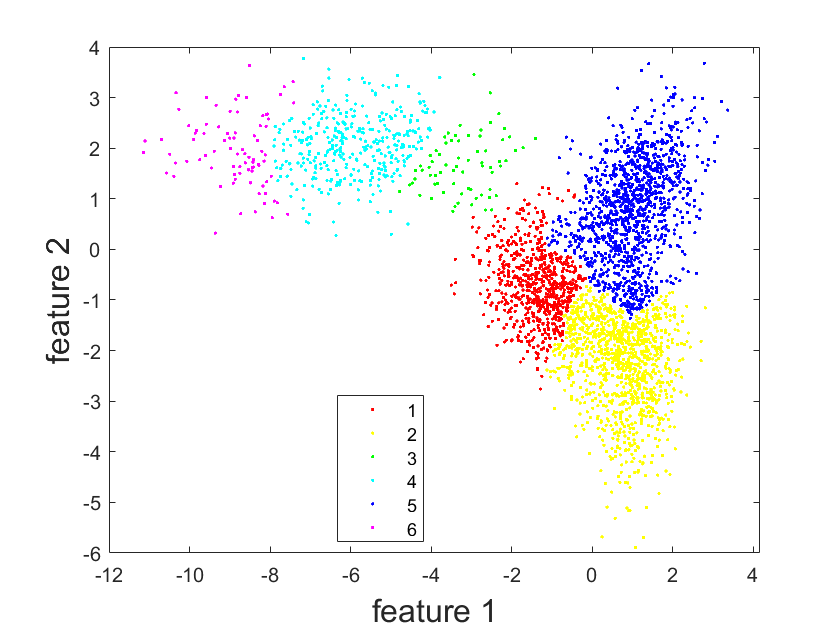

% T = cluster(Z,"maxclust",10);
T = clusterdata(X,'Linkage','average','distance', 'euclidean',"maxclust",6);
gscatter(X(:,1),X(:,2),T)
xlabel('feature 1',"FontSize",16)
ylabel('feature 2',"FontSize",16)

% Single
Z = linkage(X,'single')

Z = 	1.0e+03 *

    1.6220    1.7110    0.0000
    0.7360    0.8030    0.0000
    2.0220    2.8760    0.0000
    0.7240    0.7980    0.0000
    2.5970    2.9230    0.0000
    2.3170    2.9930    0.0000
    1.5710    2.8940    0.0000
    0.6820    0.6900    0.0000
    0.5870    0.9100    0.0000
    1.1210    2.9330    0.0000


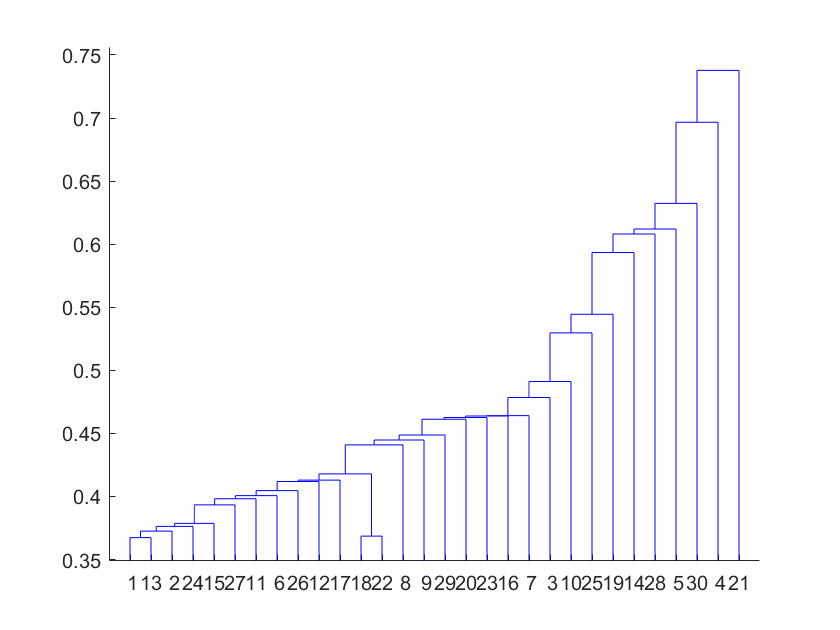

dendrogram(Z)

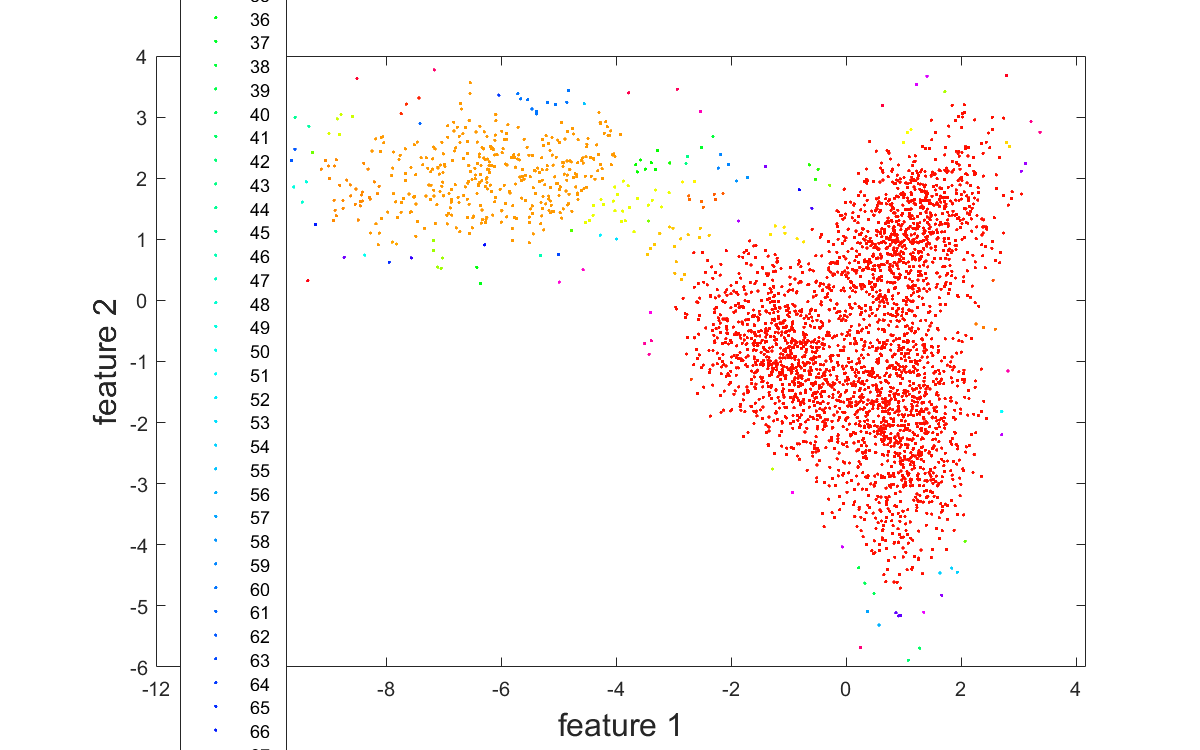

hold off

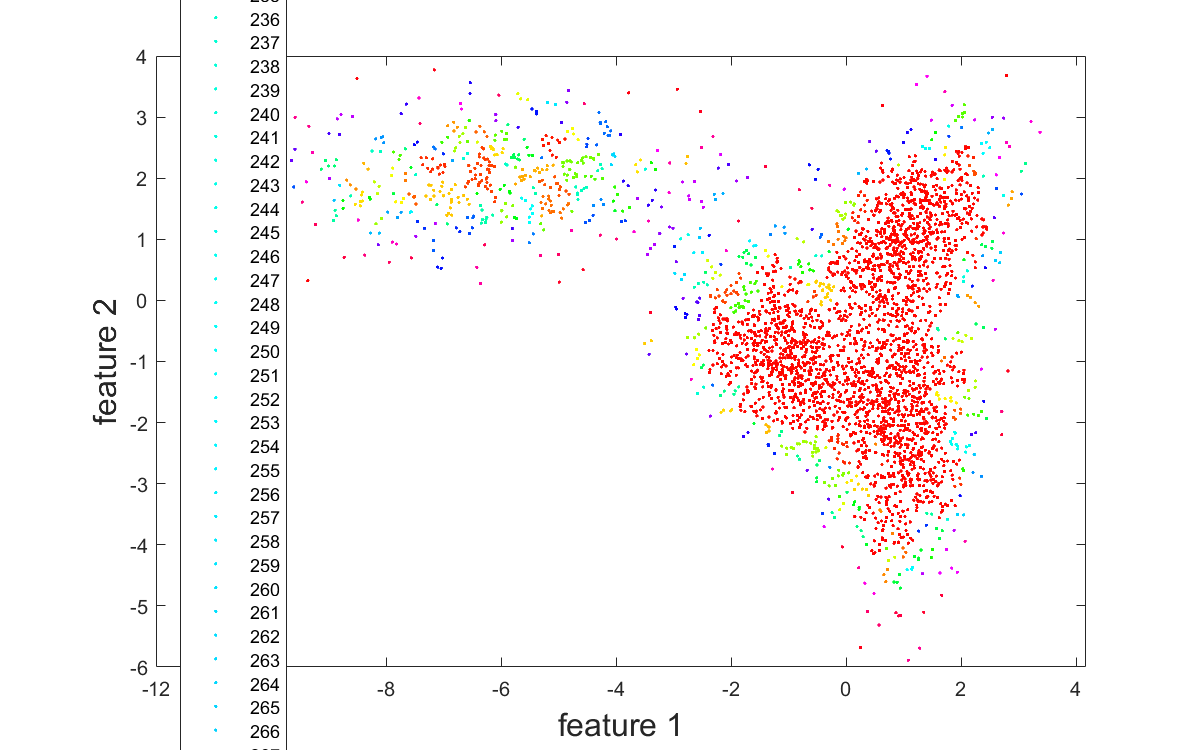

T = clusterdata(X,'Linkage','single','distance', 'euclidean',"maxclust",500);
% T = cluster(Z,"maxclust",4);
gscatter(X(:,1),X(:,2),T)
xlabel('feature 1',"FontSize",16)
ylabel('feature 2',"FontSize",16)

## Data set 2

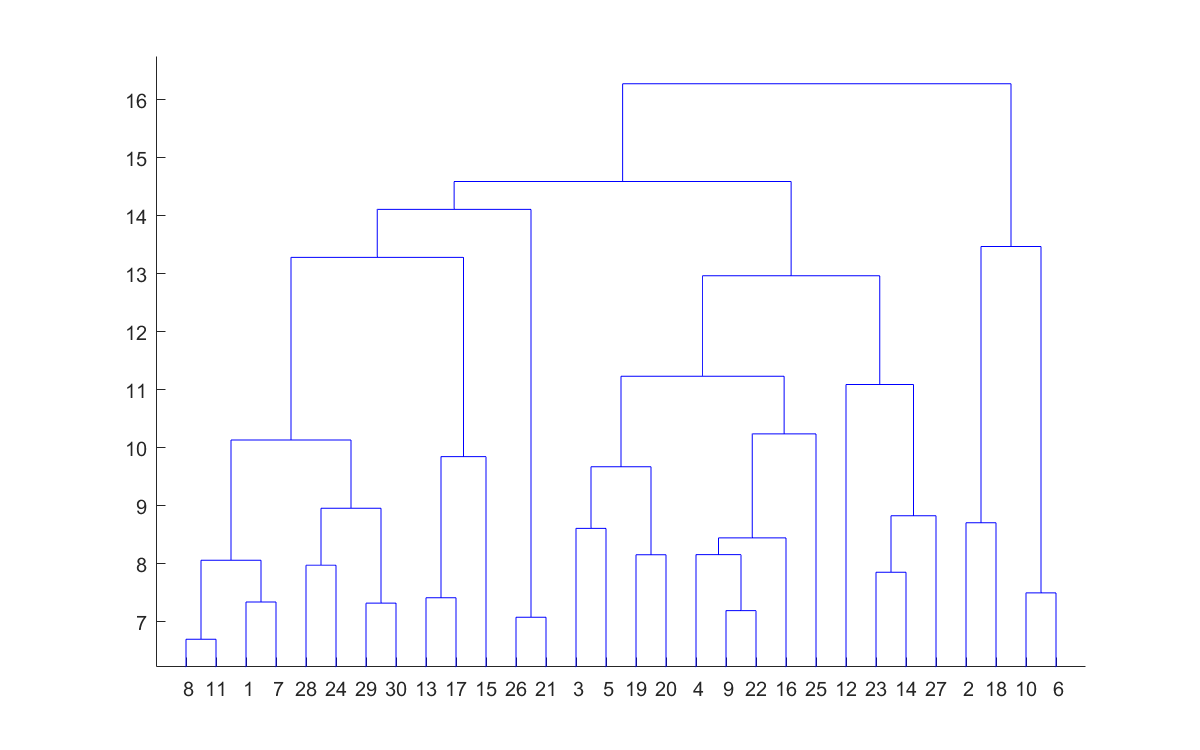

X = dataset2;
% eva = evalclusters(X,"linkage","gap","KList",[2:20])
Z = linkage(X,'average');
dendrogram(Z)
T = clusterdata(X,'Linkage','average','distance', 'euclidean',"maxclust",2);
hold off

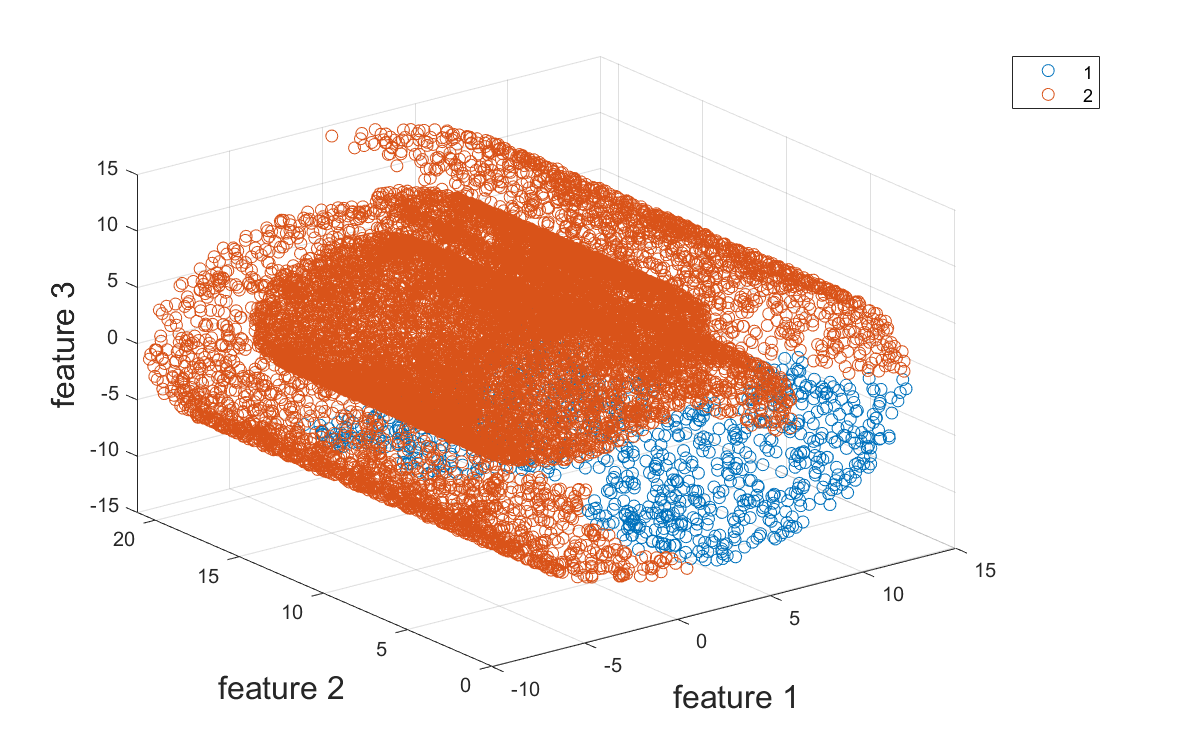

for i = 1:max(T)
    data = X(T==i,:);
    scatter3(data(:,1),data(:,2),data(:,3),"DisplayName",string(i));
    hold on 
end
hold off
legend
xlabel('feature 1',"FontSize",16)
ylabel('feature 2',"FontSize",16)
zlabel('feature 3',"FontSize",16)

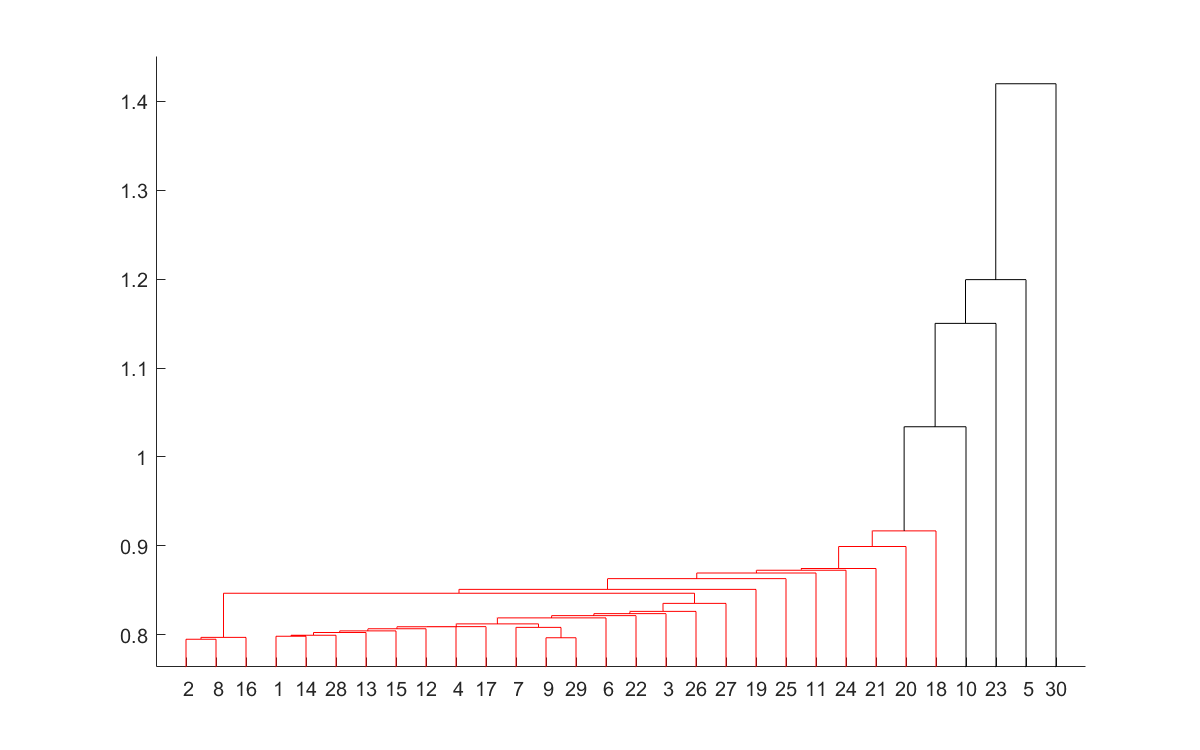


Z = linkage(X,'single',"euclidean");
dendrogram(Z,'ColorThreshold',"default")

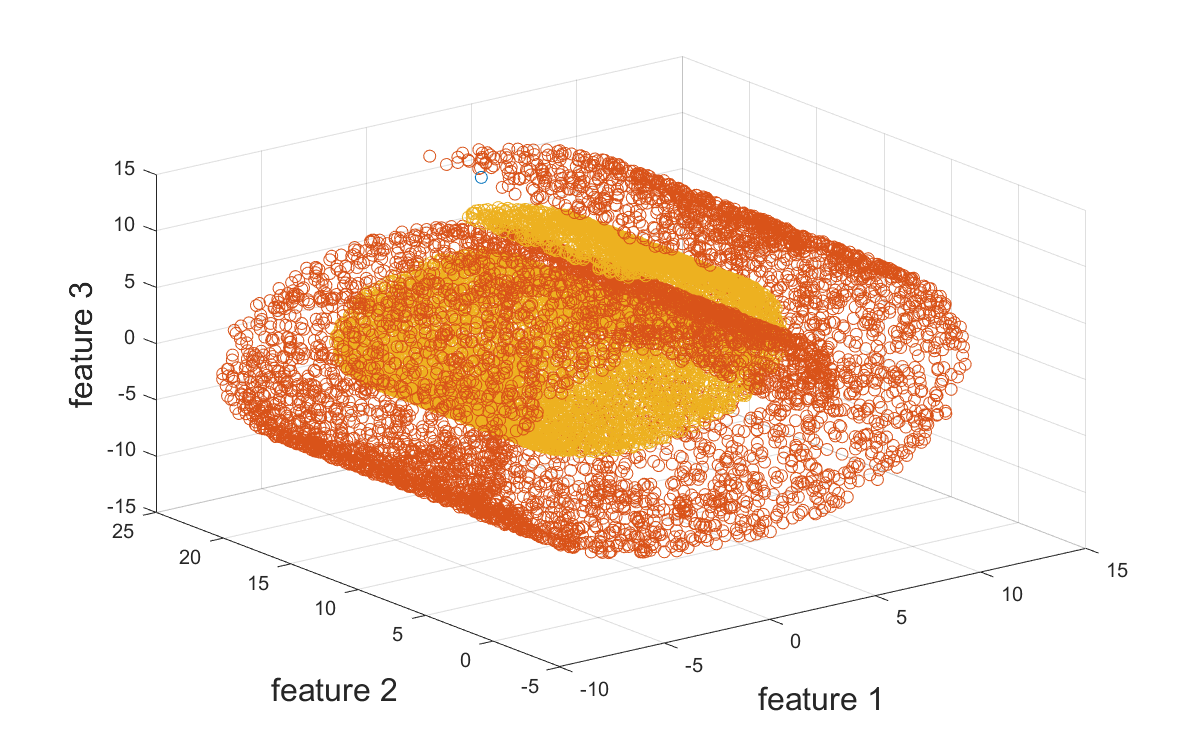

T = clusterdata(X,'Linkage','single','distance', 'euclidean',"maxclust",3);
a = inconsistent(Z,4);
for i = 1:max(T)
    data = X(T==i,:);
    scatter3(data(:,1),data(:,2),data(:,3),"DisplayName",string(i));
    hold on 
end
hold off
% legend
xlabel('feature 1',"FontSize",16)
ylabel('feature 2',"FontSize",16)
zlabel('feature 3',"FontSize",16)

## tesing

[c_idx,C] = kmeans(X,k)
for i = 1:k
    data = X(c_idx==i,:);
    scatter3(data(:,1),data(:,2), data(:,3))
    hold on
end
hold off